**exploreCSD.mlx**

%% bmcBRFS_CSD_grandAverage_loadMAT
% Are there observable differences between trial-types with LFP CSD?
% initialize variables

%% Setup
disp('start time')

start time


datetime

ans = datetime
   27-Sep-2024 12:35:39


clearvars -except LFP_trials
workingPC = 'office'; % options: 'home', 'office'
if strcmp(workingPC,'home')
    codeDir = 'C:\Users\Brock Carlson\Documents\GitHub\bmcBRFSanalysis\publicationFigures\grand average';
    dataDir = 'S:\TrialTriggeredLFPandMUA';
    plotDir = 'C:\Users\Brock Carlson\Box\Manuscripts\Maier\plotDir\CSDFigs';
    officLamAssign = importLaminarAssignments("C:\Users\Brock Carlson\Box\Manuscripts\Maier\officialLaminarAssignment_bmcBRFS.xlsx", "AnalysisList", [2, Inf]);
elseif strcmp(workingPC,'office')
    codeDir     = 'C:\Users\neuropixel\Documents\GitHub\bmcBRFSanalysis\publicationFigures\grand average';
    dataDir    = 'D:\TrialTriggeredLFPandMUA';
    plotDir = 'C:\Users\neuropixel\Box\Manuscripts\Maier\plotDir\CSDFigs';
    officLamAssign = importLaminarAssignments("C:\Users\neuropixel\Box\Manuscripts\Maier\officialLaminarAssignment_bmcBRFS.xlsx", "AnalysisList", [2, Inf]);
end
cd(codeDir)
cd(dataDir)

if ~exist('LFP_trials','var')
    tic
    load('LFP_trials.mat') % format is LFP_trials{penetration,1}{cond,1}{trial,flash}
    toc
end



%% For loop
averageCSDMatrix_diopDichop = nan(2001,15,2,31);
averageCSDMatrix_BRFS       = nan(2001,15,2,31);
for penetration = 1:size(LFP_trials,1)
    
    probeName = char(officLamAssign.Session_probe_(penetration,1));
    fileToLoad = strcat('sortedData_',probeName(1:19),'.mat');

    granBtm = officLamAssign.stFold4c(penetration); % channel corresponding to the bottom of layer 4c
    if isnan(granBtm)
        warning(strcat('no sink found on _',fileToLoad))
        continue
    end
    % Calculate V1 ch boundaries
    v1Top = granBtm - 9;
    v1Btm = granBtm + 5;
    v1Ch = v1Top:v1Btm;
    % limit ch to cortex only
    if strcmp(string(officLamAssign.ChToUse(penetration)),"1:32")
        if any(v1Ch > 32) || any(v1Ch < 1)
            warning('skipping session without full column for now')
            disp(fileToLoad)
            continue
        end
    elseif strcmp(string(officLamAssign.ChToUse(penetration)),"33:64")
        if any(v1Ch > 64) || any(v1Ch < 33)
            warning('skipping session without full column for now')
            disp(fileToLoad)
            continue
        end
    end
    
    %% Obtain Monocular preference
    % bl Sub at average level (better for plotting)
    clear array_ofMonoc1 array_ofMonoc2 array_ofMonoc3 array_ofMonoc4
    
    % Monocular
    monoc_1 = [5, 11, 13, 19]; % PO RightEye
    monoc_2 = [8, 10, 16, 18]; % PO LeftEye
    monoc_3 = [7, 9, 15, 17];  % NPO RightEye
    monoc_4 = [6, 12, 14, 20]; % NPO LeftEye
    
    % convert from cell to double and combine monocular conditions
    count = 0;
    for cond = monoc_1
        for trl = 1:size(LFP_trials{penetration,1}{cond,1},1)
            count = count + 1;
            array_ofMonoc1(:,:,count) = abs(LFP_trials{penetration,1}{cond,1}{trl,1}(:,v1Ch)); % 1000 x 32
        end
    end
    clear cond count trl 
    
    count = 0;
    for cond = monoc_2
        for trl = 1:size(LFP_trials{penetration,1}{cond,1},1)
            count = count + 1;
            array_ofMonoc2(:,:,count) = abs(LFP_trials{penetration,1}{cond,1}{trl,1}(:,v1Ch)); 
        end
    end
    clear cond count trl 
    
    
    count = 0;
    for cond = monoc_3
        for trl = 1:size(LFP_trials{penetration,1}{cond,1},1)
            count = count + 1;
            array_ofMonoc3(:,:,count) = abs(LFP_trials{penetration,1}{cond,1}{trl,1}(:,v1Ch)); 
        end
    end
    clear cond count trl 
    
    
    count = 0;
    for cond = monoc_4
        for trl = 1:size(LFP_trials{penetration,1}{cond,1},1)
            count = count + 1;
            array_ofMonoc4(:,:,count) = abs(LFP_trials{penetration,1}{cond,1}{trl,1}(:,v1Ch)); 
        end
    end
    clear cond count trl 
    
    
    % Test for monocular preference with anova
    % The anova function ignores NaN values, <undefined> values, empty 
    % characters, and empty strings in y. If factors or tbl contains NaN or 
    % <undefined> values, or empty characters or strings, the function ignores 
    % the corresponding observations in y. The ANOVA is balanced if each factor 
    % value has the same number of observations after the function disregards 
    % empty or NaN values. Otherwise, the function performs an unbalanced 
    % ANOVA. (We will be doing an unbalanced ANOVA).
    
    % preallocate array with nan - running an unbalanced ANOVA)
    A = [size(array_ofMonoc1,3),...
        size(array_ofMonoc2,3),...
        size(array_ofMonoc3,3),...
        size(array_ofMonoc4,3)];
    maxTrls = max(A);
    minTrls = min(A);
    tuned = nan(length(v1Ch),1);
    prefMonoc = nan(length(v1Ch),1);
    
    % FOR each individual unit 
    for i = 1:length(v1Ch)
        % preallocate y based on trial count
        y = nan(maxTrls,4);
        % create an array of each trial's median response for each monoc 
        % condition (trl x 4 monoc)
        y(1:size(array_ofMonoc1,3),1) = median(squeeze(array_ofMonoc1(200:450,i,:)),1)'; % median of each trial after stim onset
        y(1:size(array_ofMonoc2,3),2) = median(squeeze(array_ofMonoc2(200:450,i,:)),1)'; % median of each trial after stim onset
        y(1:size(array_ofMonoc3,3),3) = median(squeeze(array_ofMonoc3(200:450,i,:)),1)'; % median of each trial after stim onset
        y(1:size(array_ofMonoc4,3),4) = median(squeeze(array_ofMonoc4(200:450,i,:)),1)'; % median of each trial after stim onset
        % Now we perform baseline subtraction
        % First we get the blAvg for this contact across all trials
        y_bl(1,1) = median(median(squeeze(array_ofMonoc1(100:200,i,:)),1)');
        y_bl(1,2) = median(median(squeeze(array_ofMonoc2(100:200,i,:)),1)');
        y_bl(1,3) = median(median(squeeze(array_ofMonoc3(100:200,i,:)),1)');
        y_bl(1,4) = median(median(squeeze(array_ofMonoc4(100:200,i,:)),1)');
        y_blSub = y - median(y_bl);
        p = anova1(y_blSub,[],'off');
        if p < .05
            tuned(i,1) = true;
        else
            tuned(i,1) = false;
        end
        % Now we find the maximum response
        [M,maxRespIdx] = max(median(y_blSub,1,"omitmissing"));
        prefMonoc(i,1) = maxRespIdx;
        % And assign the null condition
        if maxRespIdx == 1
            nullRespIdx = 4;
        elseif maxRespIdx == 2
            nullRespIdx = 3;
        elseif maxRespIdx == 3
            nullRespIdx = 2;
        elseif maxRespIdx == 4
            nullRespIdx = 1;
        end
        nullMonoc(i,1) = nullRespIdx;
    end
   

    for i = 1:length(v1Ch)
        % % monoc_1 = [5, 11, 13, 19]; % PO RightEye
        % % monoc_2 = [8, 10, 16, 18]; % PO LeftEye
        % % monoc_3 = [7, 9, 15, 17];  % NPO RightEye
        % % monoc_4 = [6, 12, 14, 20]; % NPO LeftEye
        if prefMonoc(i,1) == 1
            prefCondOnFlash(i,1) = 12;
            nullCondOnFlash(i,1) = 11;
        elseif prefMonoc(i,1) == 2
            prefCondOnFlash(i,1) = 9;
            nullCondOnFlash(i,1) = 10;
        elseif prefMonoc(i,1) == 3
            prefCondOnFlash(i,1) = 10;
            nullCondOnFlash(i,1) = 9;
        elseif prefMonoc(i,1) == 4
            prefCondOnFlash(i,1) = 11;
            nullCondOnFlash(i,1) = 12;
        end

    end
        
    overallPref = mode(prefCondOnFlash);
    if overallPref == 9
        overallNull = 10;
    elseif overallPref == 10
        overallNull = 9;
    elseif overallPref == 11
        overallNull = 12;
    elseif overallPref == 12
        overallNull = 11;
    end

    % % % %% CSD matrix across channels
    % % % chForCSDcalc = v1Ch(1)-1:v1Ch(end)+1;
    % % % % Dioptic vs dichoptic
    % % % count = 0;
    % % % for conditionNumber = [1 3]        
    % % %     % Get the number of trials for the chosen condition
    % % %     numTrials = size(LFP_trials{penetration,1}{conditionNumber,1},1);
    % % %     CSDbinocOut = nan(2001,length(v1Ch),numTrials);
    % % %     for trl = 1:numTrials
    % % %         LFPbinocTrl = LFP_trials{penetration,1}{conditionNumber,1}{trl,1}(:,chForCSDcalc); % adding ch above and below for CSD calc (to use as vaknin pad)
    % % %         blLFPbinoc = mean(LFPbinocTrl(100:200,:),1);
    % % %         LFPbinocBlSub = LFPbinocTrl-blLFPbinoc;
    % % %         CSDbinocTrl = calcCSD_classic(LFPbinocBlSub);
    % % %         CSDbinocOut(:,:,trl) = CSDbinocTrl(:,2:16); % limit to origional V1 ch lim
    % % %     end
    % % %     % Average across trials and save output
    % % %     count = count + 1; % for pref vs null
    % % %     averageCSDMatrix_diopDichop(:,:,count,penetration) = median(CSDbinocOut,3); % Average across trl. averageCSDMatrix is (ch1 x ch2 x cond x penetration)
    % % % end
    % % % 
    % % % % BRFS pref vs null
    % % % count = 0;
    % % % for conditionNumber = [overallPref overallNull]        
    % % %     % Get the number of trials for the chosen condition
    % % %     numTrials = size(LFP_trials{penetration,1}{conditionNumber,1},1);
    % % %     CSDflashOut = nan(2001,length(v1Ch),numTrials);
    % % %     for trl = 1:numTrials
    % % %         LFPflashTrl = LFP_trials{penetration,1}{conditionNumber,1}{trl,1}(:,chForCSDcalc);
    % % %         blLFPflash = mean(LFPflashTrl(100:200,:),1);
    % % %         LFPflashBlSub = LFPflashTrl-blLFPflash;
    % % %         CSDflashTrl = calcCSD_classic(LFPflashBlSub);
    % % %         CSDflashOut(:,:,trl) = CSDflashTrl(:,2:16);
    % % %     end
    % % %     % Average across trials and save output
    % % %     count = count + 1; % for pref vs null
    % % %     averageCSDMatrix_BRFS(:,:,count,penetration) = median(CSDflashOut,3); % Average across trl. averageCSDMatrix is (ch1 x ch2 x cond x penetration)
    % % % end

    chForCSDcalc = v1Ch(1)-1:v1Ch(end)+1;
    % Dioptic vs dichoptic
    count = 0;
    for conditionNumber = [1 3]        
        % Get the number of trials for the chosen condition
        numTrials = size(LFP_trials{penetration,1}{conditionNumber,1},1);
        CSDbinocOut = nan(2001,length(v1Ch),numTrials);
        for trl = 1:numTrials
            LFPbinocTrl = LFP_trials{penetration,1}{conditionNumber,1}{trl,1}(:,chForCSDcalc); % adding ch above and below for CSD calc (to use as vaknin pad)
            CSDbinocTrl = calcCSD_classic(LFPbinocTrl);
            CSDbinocOut(:,:,trl) = CSDbinocTrl(:,2:16); % limit to origional V1 ch lim
        end
        %convert to % change
        trlAvgBinoc = median(CSDbinocOut,3); 
        blCSDbinoc = mean(trlAvgBinoc(100:200,:),1);
        CSD_percentChange = 100*((trlAvgBinoc-blCSDbinoc)./blCSDbinoc);
        % Average across trials and save output
        count = count + 1; % for pref vs null
        averageCSDMatrix_diopDichop(:,:,count,penetration) = median(CSD_percentChange,3); % Average across trl. averageCSDMatrix is (ch1 x ch2 x cond x penetration)
    end

    % BRFS pref vs null
    count = 0;
    for conditionNumber = [overallPref overallNull]        
        % Get the number of trials for the chosen condition
        numTrials = size(LFP_trials{penetration,1}{conditionNumber,1},1);
        CSDflashOut = nan(2001,length(v1Ch),numTrials);
        for trl = 1:numTrials
            LFPflashTrl = LFP_trials{penetration,1}{conditionNumber,1}{trl,1}(:,chForCSDcalc);
            CSDflashTrl = calcCSD_classic(LFPflashTrl);
            CSDflashOut(:,:,trl) = CSDflashTrl(:,2:16);
        end
        %convert to % change
        trlAvgFlash = median(CSDflashOut,3); 
        blCSDbinoc = mean(trlAvgFlash(100:200,:),1);
        CSD_percentChange = 100*((trlAvgFlash-blCSDbinoc)./blCSDbinoc);
        % Average across trials and save output
        count = count + 1; % for pref vs null
        averageCSDMatrix_BRFS(:,:,count,penetration) = median(CSD_percentChange,3); % Average across trl. averageCSDMatrix is (ch1 x ch2 x cond x penetration)
    end


    disp(strcat('Done with file number: ',string(penetration)))
end

Done with file number:1
Done with file number:2
Done with file number:3
Done with file number:4


Done with file number:6


Done with file number:8
Done with file number:9
Done with file number:10
Done with file number:11
Done with file number:12
Done with file number:13
Done with file number:14
Done with file number:15
Done with file number:16
Done with file number:17
Done with file number:18
Done with file number:19
Done with file number:20
Done with file number:21
Done with file number:22
Done with file number:23
Done with file number:24
Done with file number:25


sortedData_221209_J_bmcBRFS002.mat


Done with file number:27
Done with file number:28
Done with file number:29


sortedData_221215_J_bmcBRFS001.mat


Done with file number:31


Ok, now that the individual conditions for each penetration have been organized and CSD calculated from raw LFP,

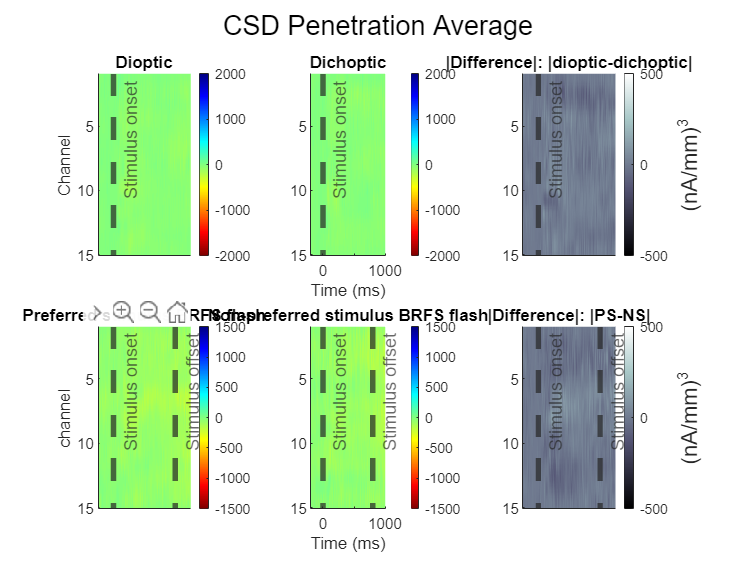

%% plot dioptic vs dichoptic
grandAverageCSD_diopDichop = median(averageCSDMatrix_diopDichop,4,"omitmissing"); % average across penetration
filterCSD_dioptic = filterCSD(grandAverageCSD_diopDichop(1:1201,:,1)',.05);
filterCSD_dichoptic = filterCSD(grandAverageCSD_diopDichop(1:1201,:,2)',.05);

f = figure; 
% set(f,"Position",[-1828 -37 1584 856])
% Visualize the CSD matrix
% dioptic
ax(1) = subplot(2,3,1);
imagesc(-200:1000,1:15,filterCSD_dioptic);
oldcmap = colormap(ax(1),'jet');
newcmap = colormap(flipud(oldcmap));
colormap(ax(1),newcmap)
clim([-2000 2000]);
% xlabel('Time (ms)');
ylabel('Channel');
cb = colorbar(); 
% ylabel(cb,'(nA/mm)^3','FontSize',12)
xl = xline(0,'--','Stimulus onset','LineWidth',3);
title('Dioptic');
box('off')
set(gca,'XTick',[])



%dichoptic
ax(2) = subplot(2,3,2);
imagesc(-200:1000,1:15,filterCSD_dichoptic);
colormap(ax(2),newcmap)
clim([-2000 2000]);
xlabel('Time (ms)');
cb = colorbar(); 
xl = xline(0,'--','Stimulus onset','LineWidth',3);
title('Dichoptic');
box('off')


% Visualize the raw diff
% First we half-wave rectify
halfWave_diopDichop = grandAverageCSD_diopDichop;
halfWave_diopDichop(halfWave_diopDichop > 0) = 0;
hwRectify_diopDichop = abs(halfWave_diopDichop);
% Then subtract dichoptic from dioptic
differenceMatrix_diopDichoip = ...
    abs(hwRectify_diopDichop(1:1201,:,1)')-abs(hwRectify_diopDichop(1:1201,:,2)');
filterCSD_binocDiff =  filterCSD(differenceMatrix_diopDichoip,.05);

ax(3) = subplot(2,3,3);
imagesc(-200:1000,1:15,filterCSD_binocDiff);
colormap(ax(3),'bone');
clim([-500 500]);
% xlabel('Time (ms)');
cb = colorbar(); 
ylabel(cb,'(nA/mm)^3','FontSize',12)
xl = xline(0,'--','Stimulus onset','LineWidth',3);
title('|Difference|: |dioptic-dichoptic|');
box('off')
set(gca,'XTick',[])




% % 
% % % Difference plot - with tStat
% % usePenetration = [1:4 6 8:25 27:29 31];
% % h = nan(15,24);
% % p = nan(15,24);
% % ci = nan(15,24,2);
% % for ch = 1:15
% %     CSDMatrix1 = squeeze(averageCSDMatrix_diopDichop(1:1201,ch,1,usePenetration)); 
% %     CSDMatrix2 = squeeze(averageCSDMatrix_diopDichop(1:1201,ch,2,usePenetration)); 
% %     for bin = 1:24
% %         tm = [1:50]+(50*(bin-1));
% %         CSD_binned1(bin,:) = abs(median(CSDMatrix1(tm,:),1));   % output should be 24xlength(usePenetration)
% %         CSD_binned2(bin,:) = abs(median(CSDMatrix2(tm,:),1));
% %         [h(ch,bin),p(ch,bin),ci(ch,bin,:),stats(ch,bin)] =...
% %             ttest2(CSD_binned1(bin,:),CSD_binned2(bin,:),'Alpha',0.05,'Tail','left');
% %         tStat_1(ch,bin) = stats(ch,bin).tstat;
% % 
% %     end
% % end
% % ax(4) = subplot(2,3,4);
% % imagesc(tStat_1);
% % colormap(ax(4),'bone');
% % cb = colorbar(); 
% % clim([-1 1]);
% % xl = xline(3.5,'--','Stimulus onset','LineWidth',3);
% % xlabel('Index of 50ms bin');
% % title('left-tail tScoreMap of |difference|');
% % 
% % % hypothesis test logical
% % ax(5) = subplot(2,3,5);
% % imagesc(h);
% % colormap(ax(5),'bone');
% % e = colorbar(); 
% % e.Label.String = "h = 1 or 0";
% % e.Label.Rotation = 270;
% % xl = xline(3.5,'--','Stimulus onset','LineWidth',3);
% % xlabel('Index of 50ms bin');
% % title('|Dichoptic > Dioptic| Hypothesis test');




%% plot BRFS
grandAverageCSD_BRFS = median(averageCSDMatrix_BRFS,4,"omitmissing"); % average across penetration
filterCSD_BRFSps = filterCSD(grandAverageCSD_BRFS(801:2001,:,1)',.05);
filterCSD_BRFSns = filterCSD(grandAverageCSD_BRFS(801:2001,:,2)',.05);

% Visualize the CSD matrix
ax(6) = subplot(2,3,4);
imagesc(-200:1000,1:15,filterCSD_BRFSps);
colormap(ax(6),newcmap)
clim([-1500 1500]);
% xlabel('Time (ms)');
ylabel('channel');
cb = colorbar(); 
% ylabel(cb,'(nA/mm)^3','FontSize',12)
xl = xline(0,'--','Stimulus onset','LineWidth',3);
xl = xline(800,'--','Stimulus offset','LineWidth',3);
title('Preferred stimulus BRFS flash');
box('off')
set(gca,'XTick',[])




ax(7) = subplot(2,3,5);
imagesc(-200:1000,1:15,filterCSD_BRFSns);
colormap(ax(7),newcmap)
clim([-1500 1500]);
xlabel('Time (ms)');
% ylabel('channel');
cb = colorbar(); 
% ylabel(cb,'(nA/mm)^3','FontSize',12)
xl = xline(0,'--','Stimulus onset','LineWidth',3);
xl = xline(800,'--','Stimulus offset','LineWidth',3);
title('Non-preferred stimulus BRFS flash');
box('off')


% Visualize the raw diff
% First we half-wave rectify
halfWave_BRFS = grandAverageCSD_BRFS;
halfWave_BRFS(halfWave_BRFS > 0) = 0;
hwRectify_BRFS = abs(halfWave_BRFS);
% Then subtract dichoptic from dioptic
differenceMatrix_BRFS = ...
    abs(hwRectify_BRFS(1:1201,:,1)')-abs(hwRectify_BRFS(1:1201,:,2)');
filterCSD_BRFSDiff =  filterCSD(differenceMatrix_BRFS,.05);

ax(8) = subplot(2,3,6);
imagesc(-200:1000,1:15,filterCSD_BRFSDiff);
colormap(ax(8),'bone');
clim([-500 500]);
% xlabel('Time (ms)');
cb = colorbar(); 
ylabel(cb,'(nA/mm)^3','FontSize',12)
xl = xline(0,'--','Stimulus onset','LineWidth',3);
xl = xline(800,'--','Stimulus offset','LineWidth',3);
title('|Difference|: |PS-NS|');
box('off')
set(gca,'XTick',[])




% % % Difference plot - with tStat
% % usePenetration = [1:4 6 8:25 27:29 31];
% % h = nan(15,24);
% % p = nan(15,24);
% % ci = nan(15,24,2);
% % for ch = 1:15
% %     CSDMatrix1 = squeeze(averageCSDMatrix_BRFS(801:2001,ch,1,usePenetration)); 
% %     CSDMatrix2 = squeeze(averageCSDMatrix_BRFS(801:2001,ch,2,usePenetration)); 
% %     for bin = 1:24
% %         tm = [1:50]+(50*(bin-1));
% %         CSD_binned1(bin,:) = abs(median(CSDMatrix1(tm,:),1));   % output should be 24xlength(usePenetration)
% %         CSD_binned2(bin,:) = abs(median(CSDMatrix2(tm,:),1));
% %         [h(ch,bin),p(ch,bin),ci(ch,bin,:),stats(ch,bin)] =...
% %             ttest2(CSD_binned1(bin,:),CSD_binned2(bin,:),'Alpha',0.05,'Tail','right');
% %         tStat_1(ch,bin) = stats(ch,bin).tstat;
% % 
% %     end
% % end
% % ax(9) = subplot(2,3,9);
% % imagesc(tStat_1);
% % colormap(ax(9),'bone');
% % cb = colorbar(); 
% % xl = xline(3.5,'--','Stimulus onset','LineWidth',3);
% % xlabel('Index of 50ms bin');
% % title('right-tail tScoreMap of |difference|');
% % 
% % % hypothesis test logical
% % ax(10) = subplot(2,3,10);
% % imagesc(h);
% % colormap(ax(10),'bone');
% % e = colorbar(); 
% % e.Label.String = "h = 1 or 0";
% % e.Label.Rotation = 270;
% % xl = xline(3.5,'--','Stimulus onset','LineWidth',3);
% % xlabel('Index of 50ms bin');
% % title('|PS > NS| Hypothesis test');



sgtitle('CSD Penetration Average')



%% Save output
%save fig
answer = questdlg('Would you like to save this figure?', ...
	'Y', ...
	'N');

% Handle response
switch answer
    case 'Yes'
        disp('alright, saving figure to plotdir')
        cd(plotDir)
        saveName = strcat('CSDPenetrationAvg_prefFromLFP.png');
        saveas(f,saveName) 
        saveName = strcat('CSDPenetrationAvg_prefFromLFP.svg');
        saveas(f,saveName)
    case 'No'
        cd(plotDir)
        disp('please see plotdir for last save')
end

please see plotdir for last save
